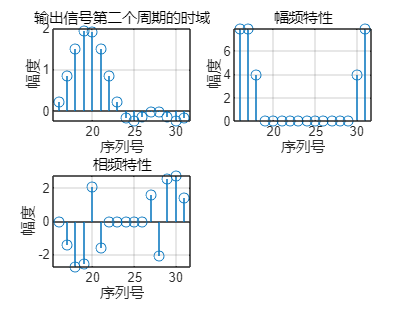

clc;clear;
f = 50;  % 基波频率
A = [0.5, 1, 0.5, 2];  % 振幅
phi = [0, pi/2, pi, -pi/2];  % 相位
N = 16;  % 采样频率倍数
L = 2 * N;  % 采样点数
fs = N * f;  % 采样频率
T = 1 / fs;  % 采样间隔
t = (0:L-1) * T;  % 采样时间
tt=N:L-1;%序列号
s = zeros(size(t));  % 初始化采样信号
for k = 1:length(A)
    sk = A(k) * cos(2 * pi * (k-1) * f * t + phi(k));
    s = s + sk;
end
H = zeros(1, N); % 初始化频域响应
H(1) = 1; 
H(2) = exp(-1i*pi*(N-1)/N);
H(3) = exp(-1i*2*pi*(N-1)/N);
H(15) = -exp(-1i*14*pi*(N-1)/N); 
H(16) = -exp(-1i*15*pi*(N-1)/N); 
r=0.999;
y=CombFilter(s,N,r);%梳状处理
z=zeros(1,48);%初始化
for i=0:1:(N/2)
    ord=i;
    yy=Resonator2(y,N,r,ord,H(i+1));% 谐振器输出
    z=z+yy;%累加
end
y=z/N;
for i=N:1:L-1%二周目
  y1(i-N+1)  =y(i+1);
end

%输出信号第二个周期的时域波形
subplot(2,2,1);
stem(tt,y(tt+1));
xlabel('序列号')
ylabel('幅度')
title('输出信号第二个周期的时域')
grid on
subplot(2,2,2);
Y=fft(y(17:32));
stem(tt,abs(Y));
xlabel('序列号')
ylabel('幅度')
title('幅频特性')
grid on
subplot(2,2,3);
stem(tt,angle(Y));
xlabel('序列号')
ylabel('幅度')
title('相频特性')
grid on